% a
x = -3:0.01:3;
f = 'sin(exp(1).^x)';
plot(x , eval(f), x , 0*x, ':');
hold on;
grid on;

z = ginput(1);

[zr, fr] = fzero(f, z(1));
plot(zr, fr, '.r', 'MarkerSize', 20);
plot(z(1), z(2), '.k', 'MarkerSize', 20);

r = fzero(@(x) sin(exp(x)), z(1));
disp(r);

    1.1447



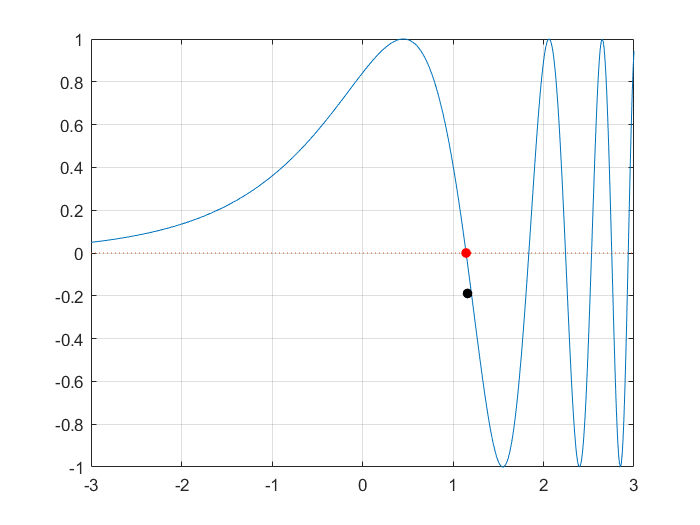

hold off;

% b
x = 0:0.01:2*pi;
f = 'sin(x.*(1-x))';
plot(x , eval(f), x , 0*x, ':');
hold on;
grid on;

z = ginput(1);
[zr, fr] = fzero(f, z(1));
plot(zr, fr, '.r', 'MarkerSize', 20);
plot(z(1), z(2), '.k', 'MarkerSize', 20);

r = fzero(@(x) sin(x*(1-x)), z(1));
disp(r);

    4.8703



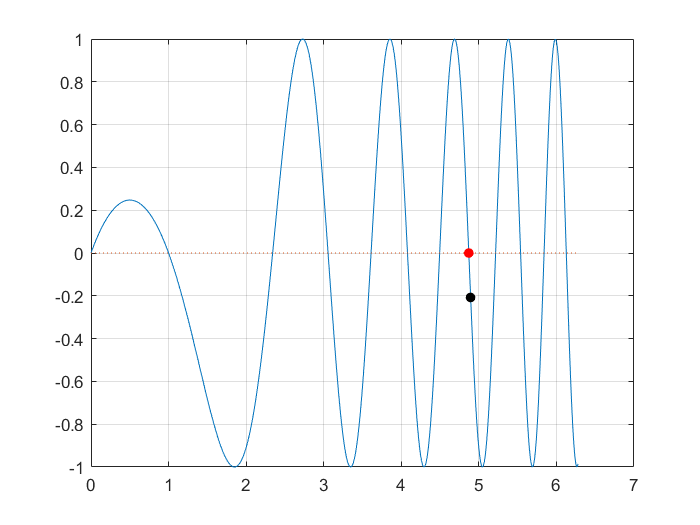

hold off;

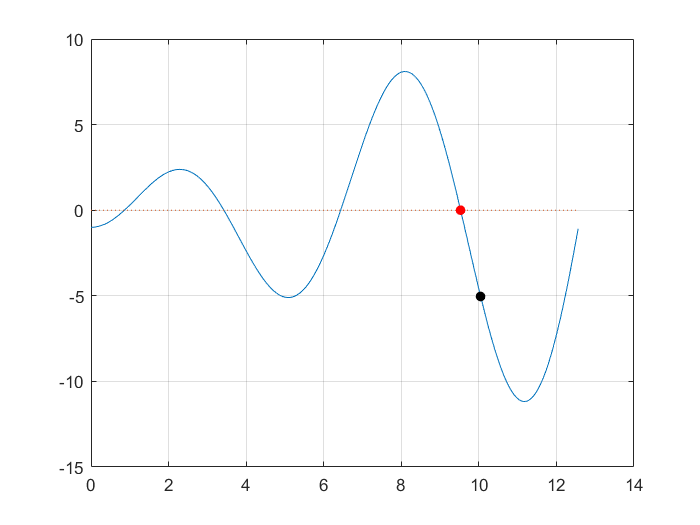

%c
x = 0:0.01:4*pi;
f = 'x.*sin(x)-cos(x)';
plot(x , eval(f), x , 0*x, ':');
hold on;
grid on;
z = ginput(1);
[zr, fr] = fzero(f, z(1));
plot(zr, fr, '.r', 'MarkerSize', 20);
plot(z(1), z(2), '.k', 'MarkerSize', 20);
hold off;

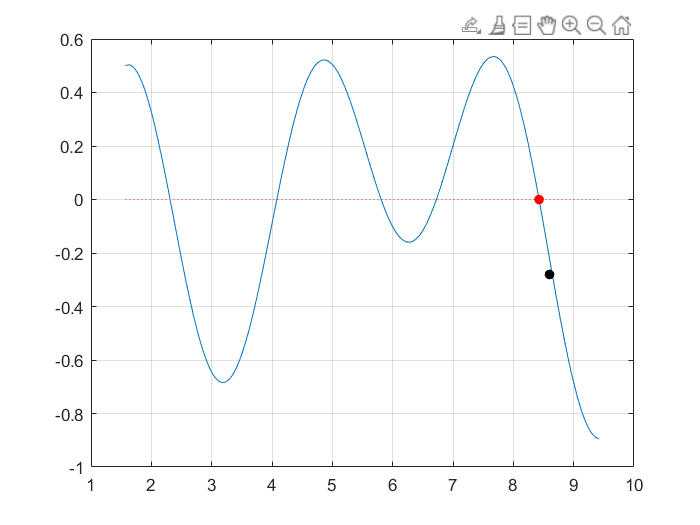

%d
x = pi/2:0.01:3*pi;
f = 'sin(x).^2+(1/2-1./x).*cos(x)-1/2';
plot(x , eval(f), x , 0*x, ':');
hold on;
grid on;
z = ginput(1);
[zr, fr] = fzero(f, z(1));
plot(zr, fr, '.r', 'MarkerSize', 20);
plot(z(1), z(2), '.k', 'MarkerSize', 20);
hold off;

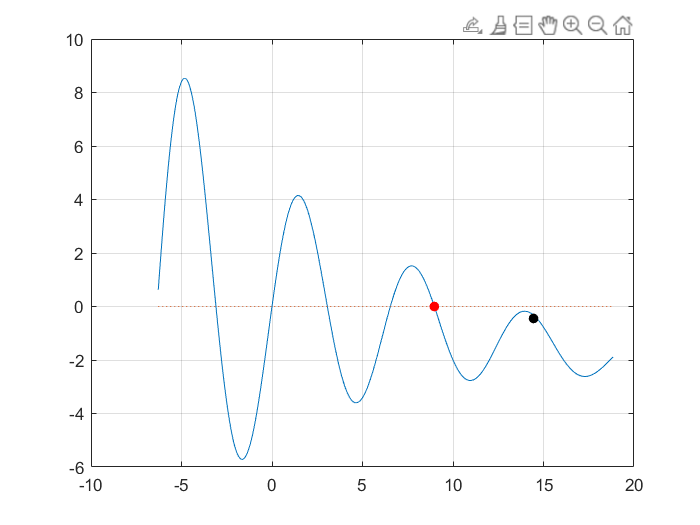

%e
x = -2*pi:0.01:6*pi;
f = '5.*exp(1).^(-0.1.*x).*sin(x)-0.1.*x';
plot(x , eval(f), x , 0*x, ':');
hold on;
grid on;
z = ginput(1);
[zr, fr] = fzero(f, z(1));
plot(zr, fr, '.r', 'MarkerSize', 20);
plot(z(1), z(2), '.k', 'MarkerSize', 20);
hold off;

%f
n = input("Please type in the 'n'");
syms u;
f = u^n - 1;
r = solve(f,u);
disp(r);

$$\left(\begin{array}{c} 1\\ -\frac{1}{2}-\frac{\sqrt{3}\,\mathrm{i}}{2}\\ -\frac{1}{2}+\frac{\sqrt{3}\,\mathrm{i}}{2} \end{array}\right)$$

%4
k = fzero(@(x)x^2+1, -1);

Exiting fzero: aborting search for an interval containing a sign change
    because NaN or Inf function value encountered during search.
(Function value at 1.7162e+154 is Inf.)
Check function or try again with a different starting value.


disp(k);

   NaN




syms u;
f = u^2+1;
r = solve(f,u);
disp(r);

$$\left(\begin{array}{c} -\mathrm{i}\\ \mathrm{i} \end{array}\right)$$

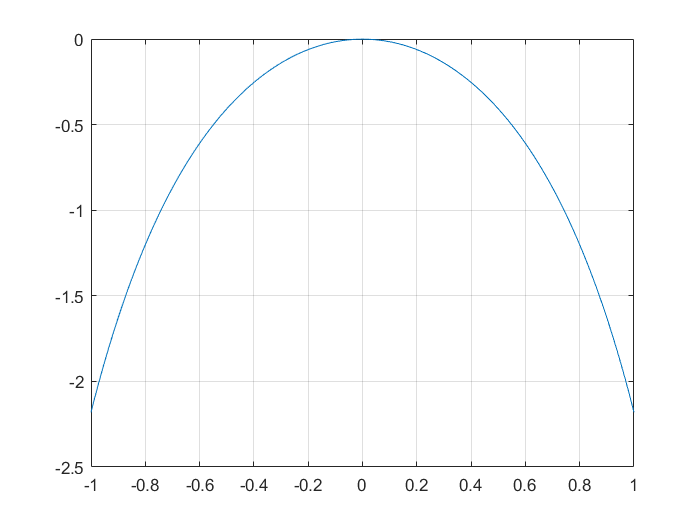

%5
x = -1:0.01:1;
y = cos(x)-exp(0.001+x.^2);
plot(x,y);
grid on;


r = fzero(@(x) cos(x)-exp(0.001+x^2), z(1));

Exiting fzero: aborting search for an interval containing a sign change
    because NaN or Inf function value encountered during search.
(Function value at -27.1425 is -Inf.)
Check function or try again with a different starting value.


disp(r);

   NaN




syms u;
f = cos(u)-exp(0.001+u^2);
r = solve(f,u);

disp(r);

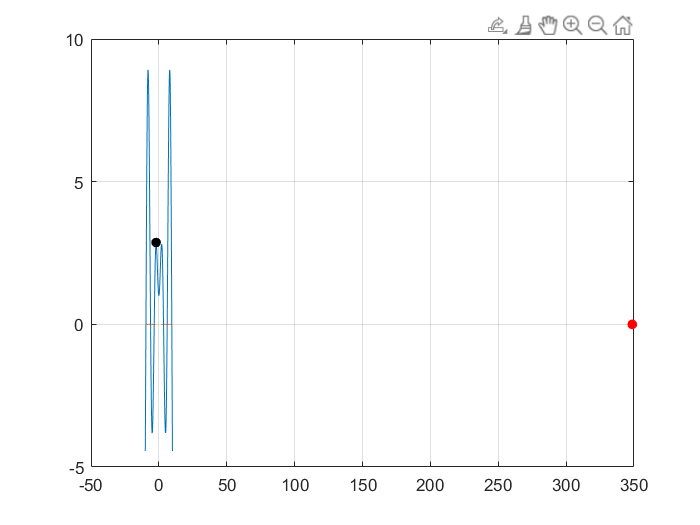

%Метод Ньютона
a = -10;
b = 10;
x = -10:0.01:10;
h = 1;
iter = 100;
eps = 0.01;
f = '1+x.*sin(x)';
plot(x , eval(f), x , 0*x, '--');
z = ginput(1);
hold on;
F = @(x)1+x.*sin(x);
DF = @(x)sin(x)+x.*cos(x);
x_0 = z(1)+a;
x_1 = z(1)+b;
X_i = (x_0+x_1)/2; 
Y_0 = F(x_0);
i = 0;
while abs(Y_0) > eps && i < iter
    X_r = X_i - F(X_i)/DF(X_i);
    X_i = X_r;
    Y = F(X_r);
    i = i+1;
end
plot(z(1), z(2), '.k', 'MarkerSize', 20);
plot(X_r, Y, '.r', 'MarkerSize', 20);
grid on;